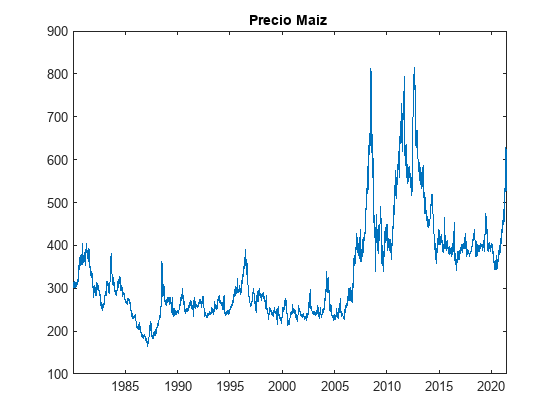

clear;
clc;
x=readtable("../datos_maiz.csv");
 plot(x.Date,x.Last)
 title("Precio Maiz ");

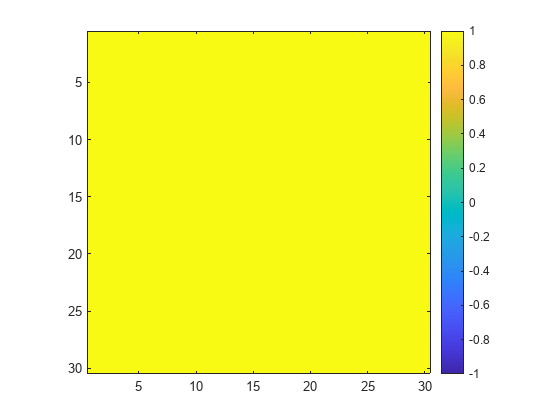

 M=30;
 N=length(x.Last);

Y = zeros(N-M+1, M); % Inicializa la matriz Y
for m = 1:M
    Y(:, m) = x.Last((1:N-M+1) + m - 1); %Llenado matriz de trayectoria
end
Covarianza=Y'*Y / (N-M+1); % matriz de covarianza

figure(2);
set(gcf,'name','Covariance matrix');
clf;
imagesc(Covarianza);
axis square
set(gca,'clim',[-1 1]);
colorbar

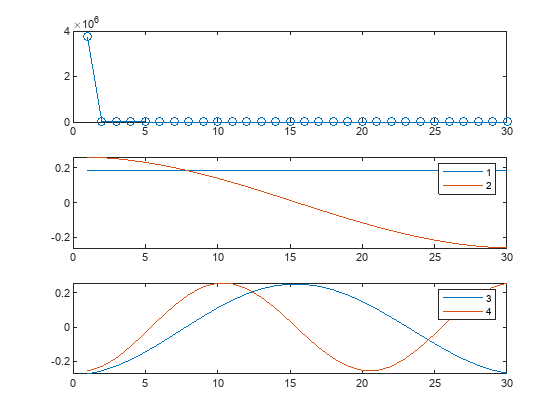


[RHO,LAMBDA] = eig(Covarianza);
LAMBDA = diag(LAMBDA);               % extrae los elementos de la diagonal
[LAMBDA,ind]=sort(LAMBDA,'descend'); % Ordena los valores propios
RHO = RHO(:,ind);                    % y vectores propios

figure(3);
set(gcf,'name','Vectores propios RHO y Valores propios LAMBDA')
clf;
subplot(3,1,1);
plot(LAMBDA,'o-');
subplot(3,1,2);
plot(RHO(:,1:2), '-');
legend('1', '2');
subplot(3,1,3);
plot(RHO(:,3:4), '-');
legend('3', '4');

PC = Y*RHO;
figure(4);
set(gcf,'name','Compontes Principales CPs')

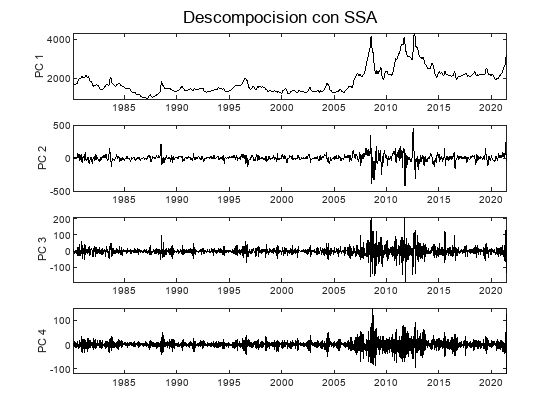

clf;
for m=1:4
  subplot(4,1,m);
  plot(x.Date(1:N-M+1),PC(:,m),'k-');
  ylabel(sprintf('PC %d',m));

  fecha_formateada=datestr(x.Date(1:N-M+1), 'yyyy-mm-dd');
  DatosFinal=table(fecha_formateada,PC(:,m),'VariableNames',{'Fecha','Precio_Cierre'});
  nombre=sprintf("ssa_modes/modo_%d.csv",m);
  writetable(DatosFinal,nombre)
end
sgtitle('Descompocision con SSA');

saveas(gcf, 'imagenes/Descompocision con SSA');

RC=zeros(N,M);
for m=1:M
  buf=PC(:,m)*RHO(:,m)'; % invertir proyeccion
  buf=buf(end:-1:1,:);
  for n=1:N % anti-diagonal averaging
    RC(n,m)=mean( diag(buf,-(N-M+1)+n) );
  end
end

figure(6);
set(gcf,'name','Serie de tiempo original X & reconstruccion RC')

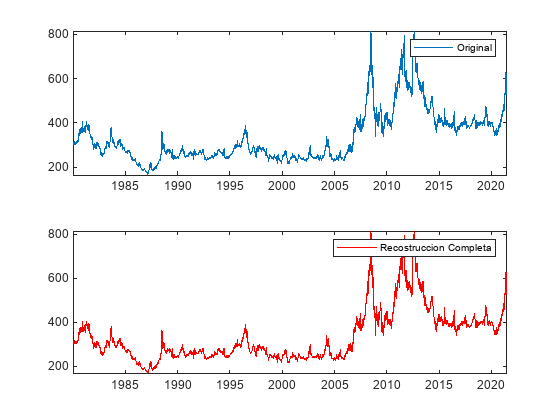

clf;
subplot(2,1,1)
plot(x.Date,x.Last);
legend('Original');

subplot(2,1,2)
plot(x.Date,sum(RC(:,:),2),'r-')
legend("Recostruccion Completa")

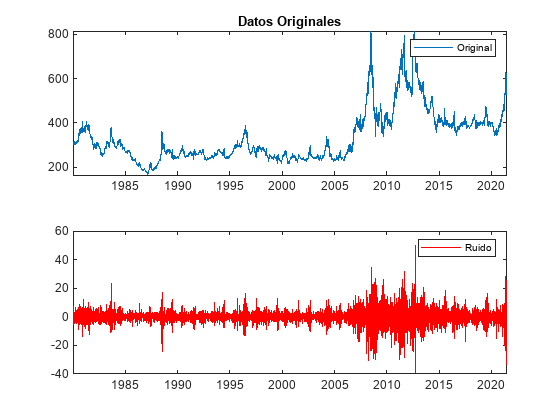


figure(7);
set(gcf,'name','Serie de tiempo original X & reconstruccion RC')
clf;
subplot(2,1,1)
plot(x.Date,x.Last);
legend("Original")
title('Datos Originales');
subplot(2,1,2)
plot(x.Date,sum(RC(:,1:4),2),'r-');
legend('Reconstruction with RCs 1-4');
title('Reconstrucción con SSA');
saveas(gcf, 'imagenes/Reconstruccion con SSA');

fecha_formateada=datestr(x.Date, 'yyyy-mm-dd');
DatosFinal=table(fecha_formateada,sum(RC(:,1:3),2),'VariableNames',{'Fecha','Precio_Cierre'});
writetable(DatosFinal,"" + ...
    "SSA_datos.csv")

figure(8);
plot(x.Date,sum(RC(:,5:30),2),'r-');
legend('Ruido');

fecha_formateada=datestr(x.Date, 'yyyy-mm-dd');
DatosFinal=table(fecha_formateada,sum(RC(:,5:30),2),'VariableNames',{'Fecha','Precio_Cierre'});
  nombre=sprintf("ssa_modes/ruido.csv");
  writetable(DatosFinal,nombre)
